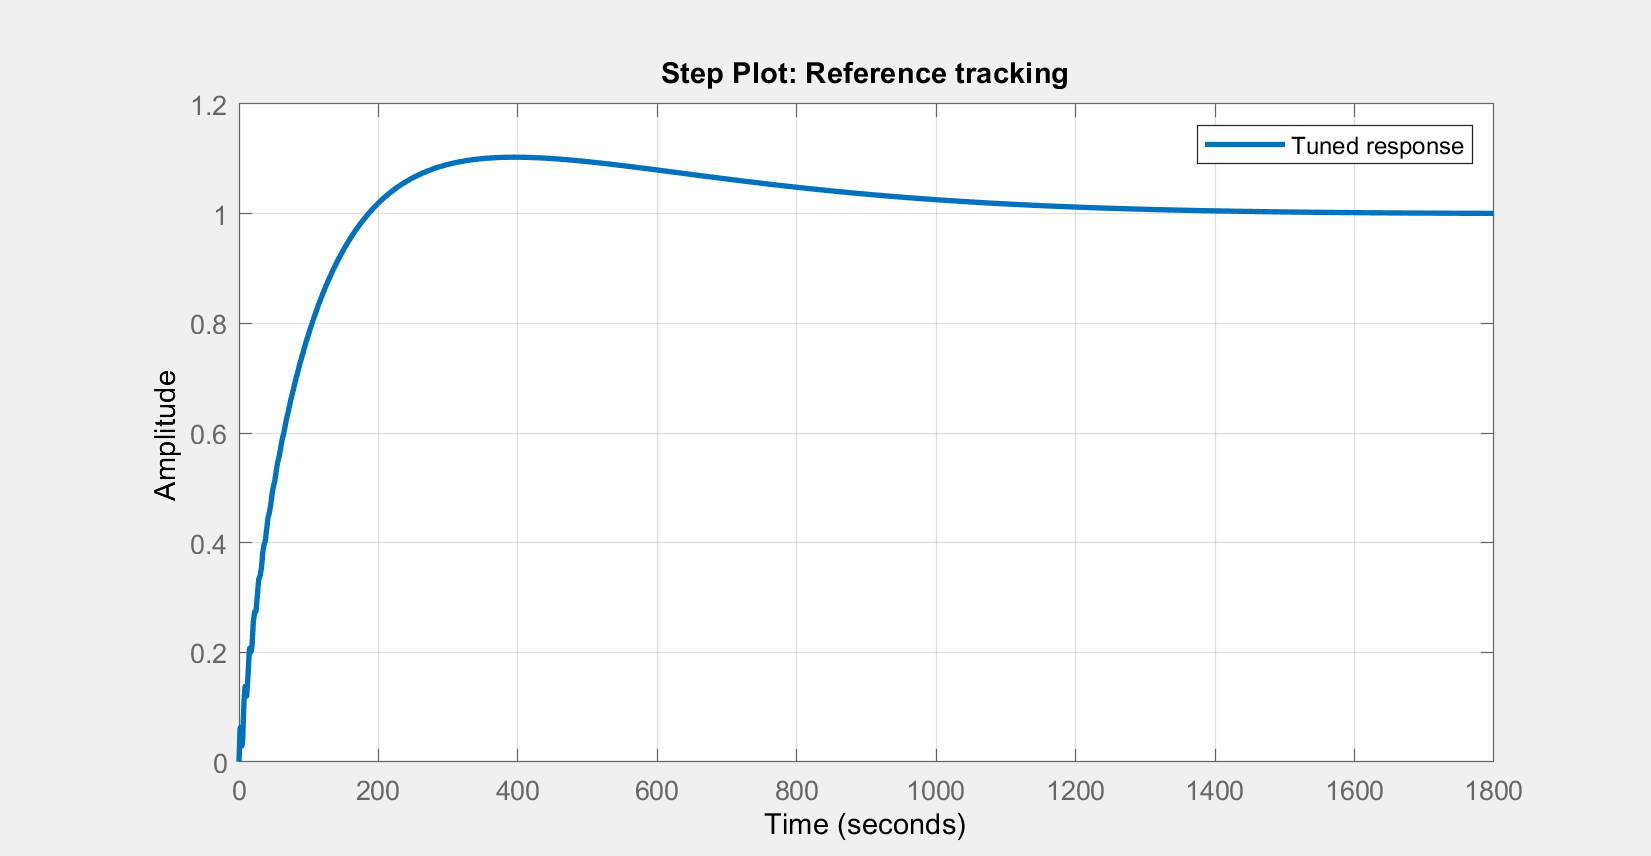

% source: Lateral Motion Control of Boeing 747 by Using Full-Order Observer
clear all
close all
clc

global A
global B
global control

A = [0       0        1        0         0;
     0    -0.0558  -0.9968   0.0802   0.0415;
     0    0.598    -0.115   -0.0318      0;
     0     -3.05    0.388   -0.4650      0;
     0       0     0.0805      1         0];
B = [0; 0.00729; -0.475; 0.153; 0];
C = [1 0 0 0 0];
D = 0;

sys = ss(A,B,C,D);

sysd = c2d(sys, 0.02);
pidTuner(sysd,'pid');


x0 = [0; 0; 0; 0; 0;];

# Timing Parameters

dt = 0.02;
t_total = 10;
t_span = 0:dt:t_total;

% target measurement - pulse
ref_fuc = @(i) 5-mod(floor(i*dt/4),2);
ref = zeros(size(t_span,2),1);
for i = 1:length(ref)
    ref(i,1) = ref_fuc(i);
end

# PID Parameters

global windupGuard;
global proportional_gain;
global integral_gain;
global derivative_gain;
global prev_error;
global int_error;
global control;

% set these as needed
control = 0;
windupGuard = 100;
proportional_gain = -0.0008629;%-0.0008629;
integral_gain = -8.991e-7;%-8.991e-7;
derivative_gain = -0.1228;%-0.1228;
 
% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

# Simulation - No attacks

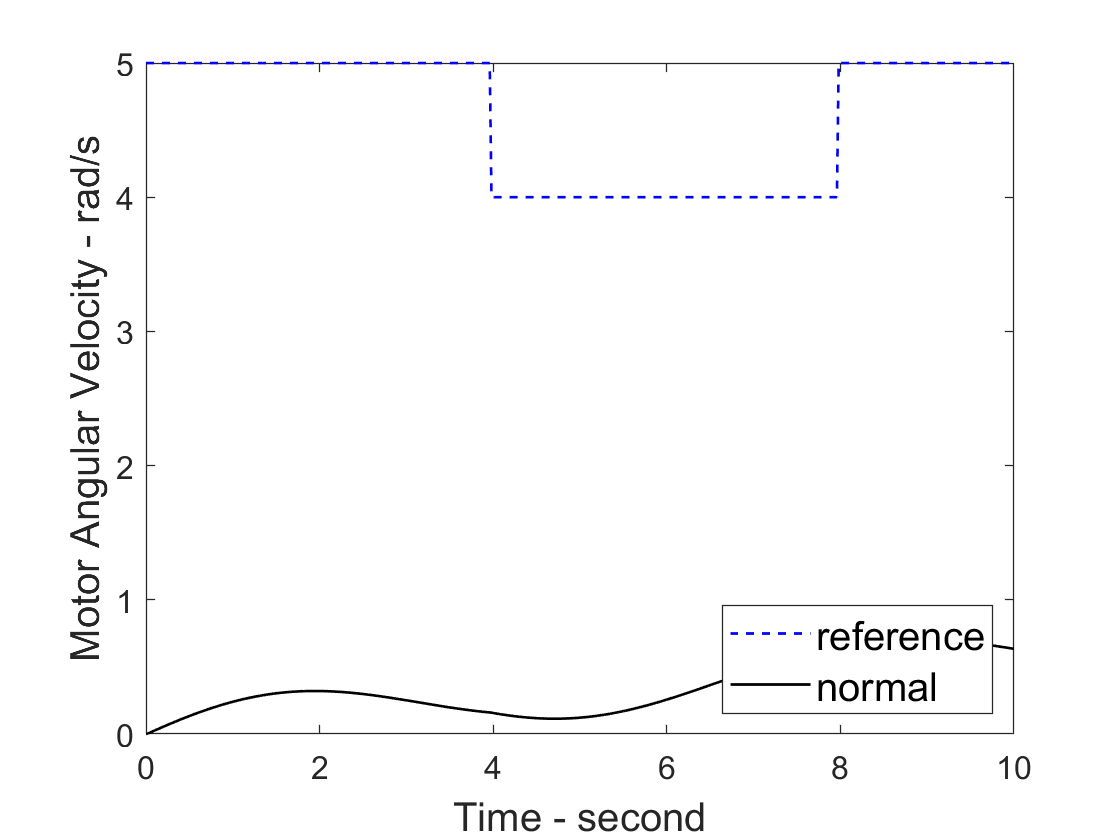

close all

% this is the zeroize function
prev_error = 0.0;
int_error = 0.0;

x = zeros(size(t_span,2),size(x0,1));
x(1,:) = x0';
xlast = x0;
y = C * x0;

for i = 2:(t_total/dt+1)
    error = ref(i,1) - y(end,1);
    pid_update(error, dt);
    [y,t,xtemp] = lsim(sys,control*ones(size(0:dt:dt))',(0:dt:dt),xlast);
%     xr = zeros(1, size(x0,2));
%     xr(1:1) = ref(i,1);
%     control = u(xlast,xr)
%     [T, xtemp] = ode45(@dynamics, [0 dt], xlast);
%     y = C * xtemp(end,:)';
    xlast = xtemp(end,:);
    x(i,:) = xlast;
    xlast = xlast';
end

plot(t_span,ref(:,1),'b--',t_span,x(:,1),'k', 'LineWidth', 1);
set(gca,'FontSize',12)
ylabel('Motor Angular Velocity - rad/s','FontSize',15);
xlabel('Time - second','FontSize',15);
legend('reference','normal','Location','SouthEast','FontSize',15);